% 繪製檢定力圖，如論文之圖 2 ~ 圖 6

clear
dirpath = "new_data/";
filename =[ "POWER_T(10)_alpha_005";
            "POWER_KHN(normal)_alpha_005";
            "POWER_KHN(GEP)_alpha_005";
            "POWER_PearsonVII(m10)_alpha_005";
            "POWER_PearsonII(m10)_alpha_005";
            "POWER_PearsonII(m05)_alpha_005";
            "POWER_PearsonII(m0)_alpha_005";
            "POWER_SkewNormal(a2)_alpha_005";
            "POWER_SkewNormal(a4)_alpha_005";
            "POWER_MixedMVN(05B)_alpha_005";
            "POWER_MixedMVN(05mu3)_alpha_005";
            "POWER_MixedNormal(09B)_alpha_005";
            "POWER_MixedNormal(09mu3)_alpha_005";
            "POWER_MixedNormal(079mu3)_alpha_005";
            "POWER_BurrParetoLogistic(a1)_alpha_005";
            "POWER_Normal_alpha_001";
            "POWER_Normal_alpha_005"];
fIdx = 15;
filename(fIdx)

ans = "POWER_BurrParetoLogistic(a1)_alpha_005"

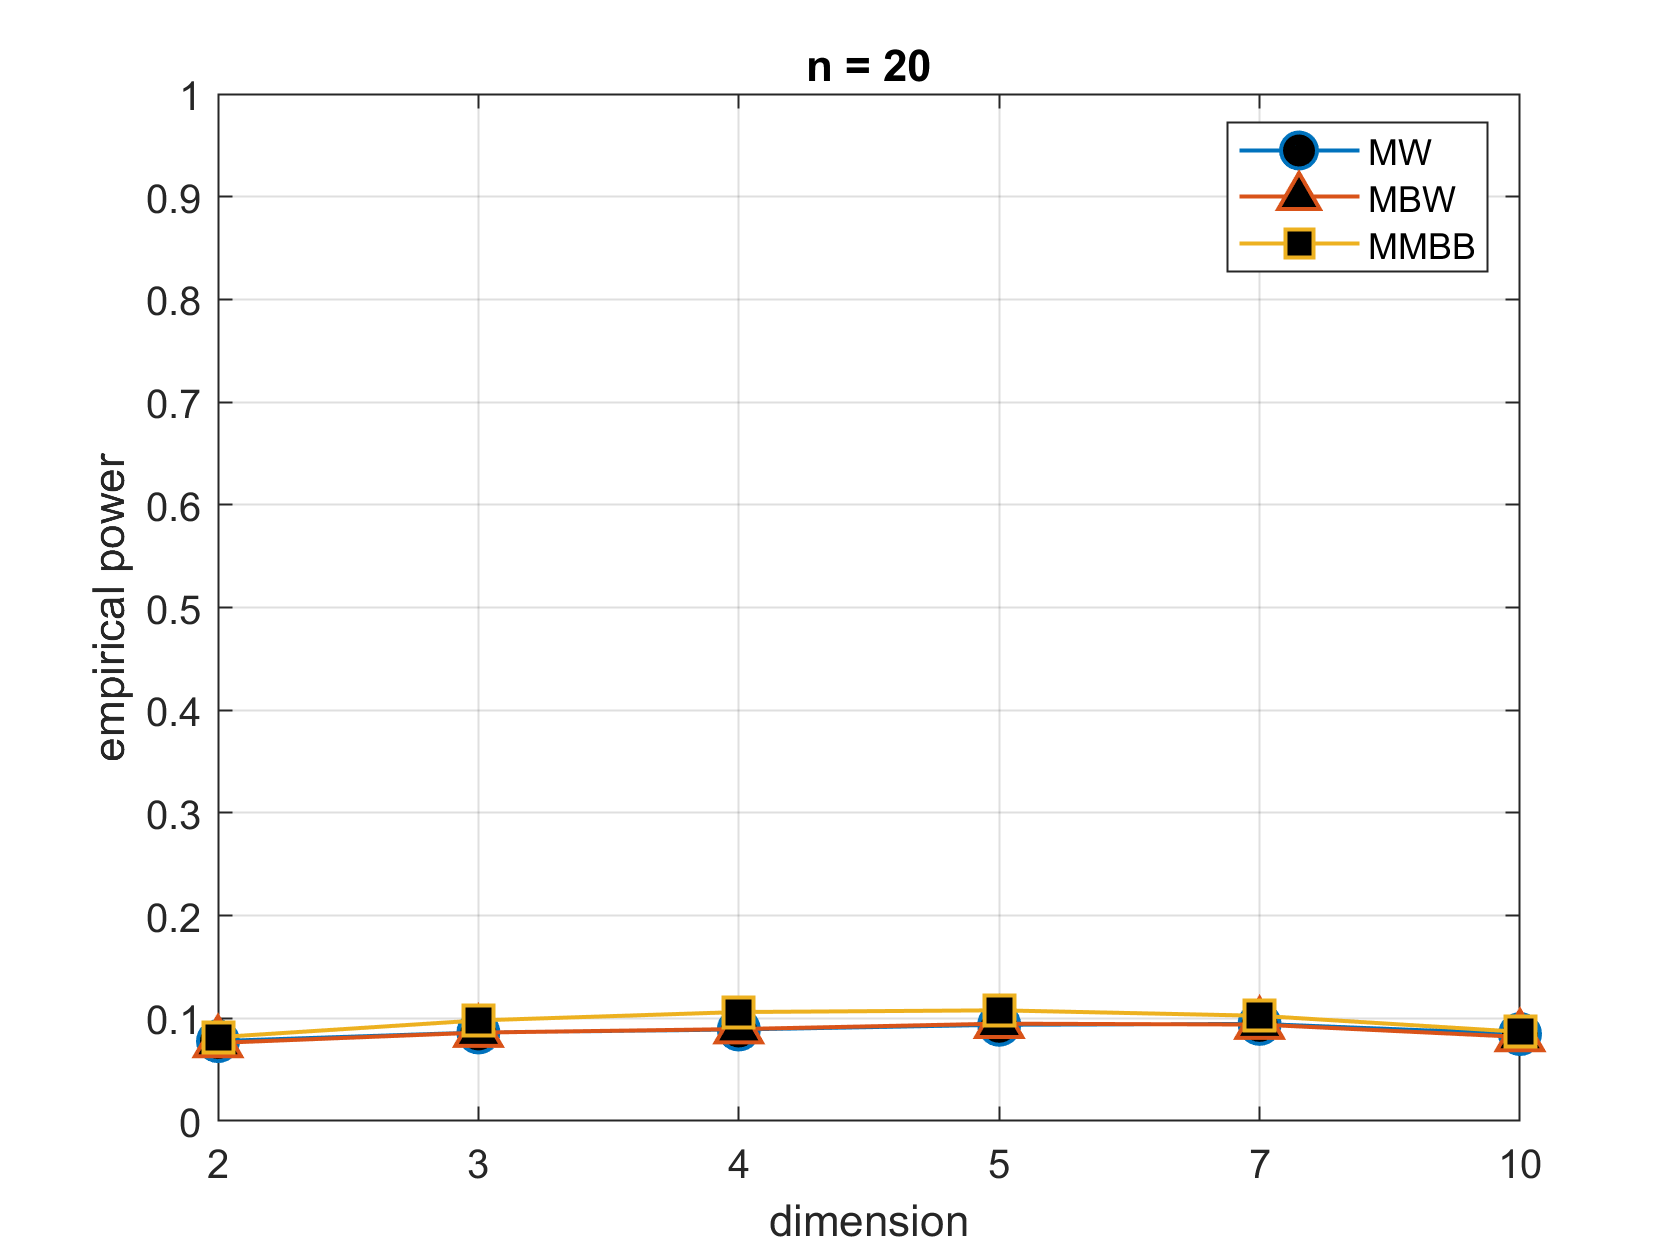

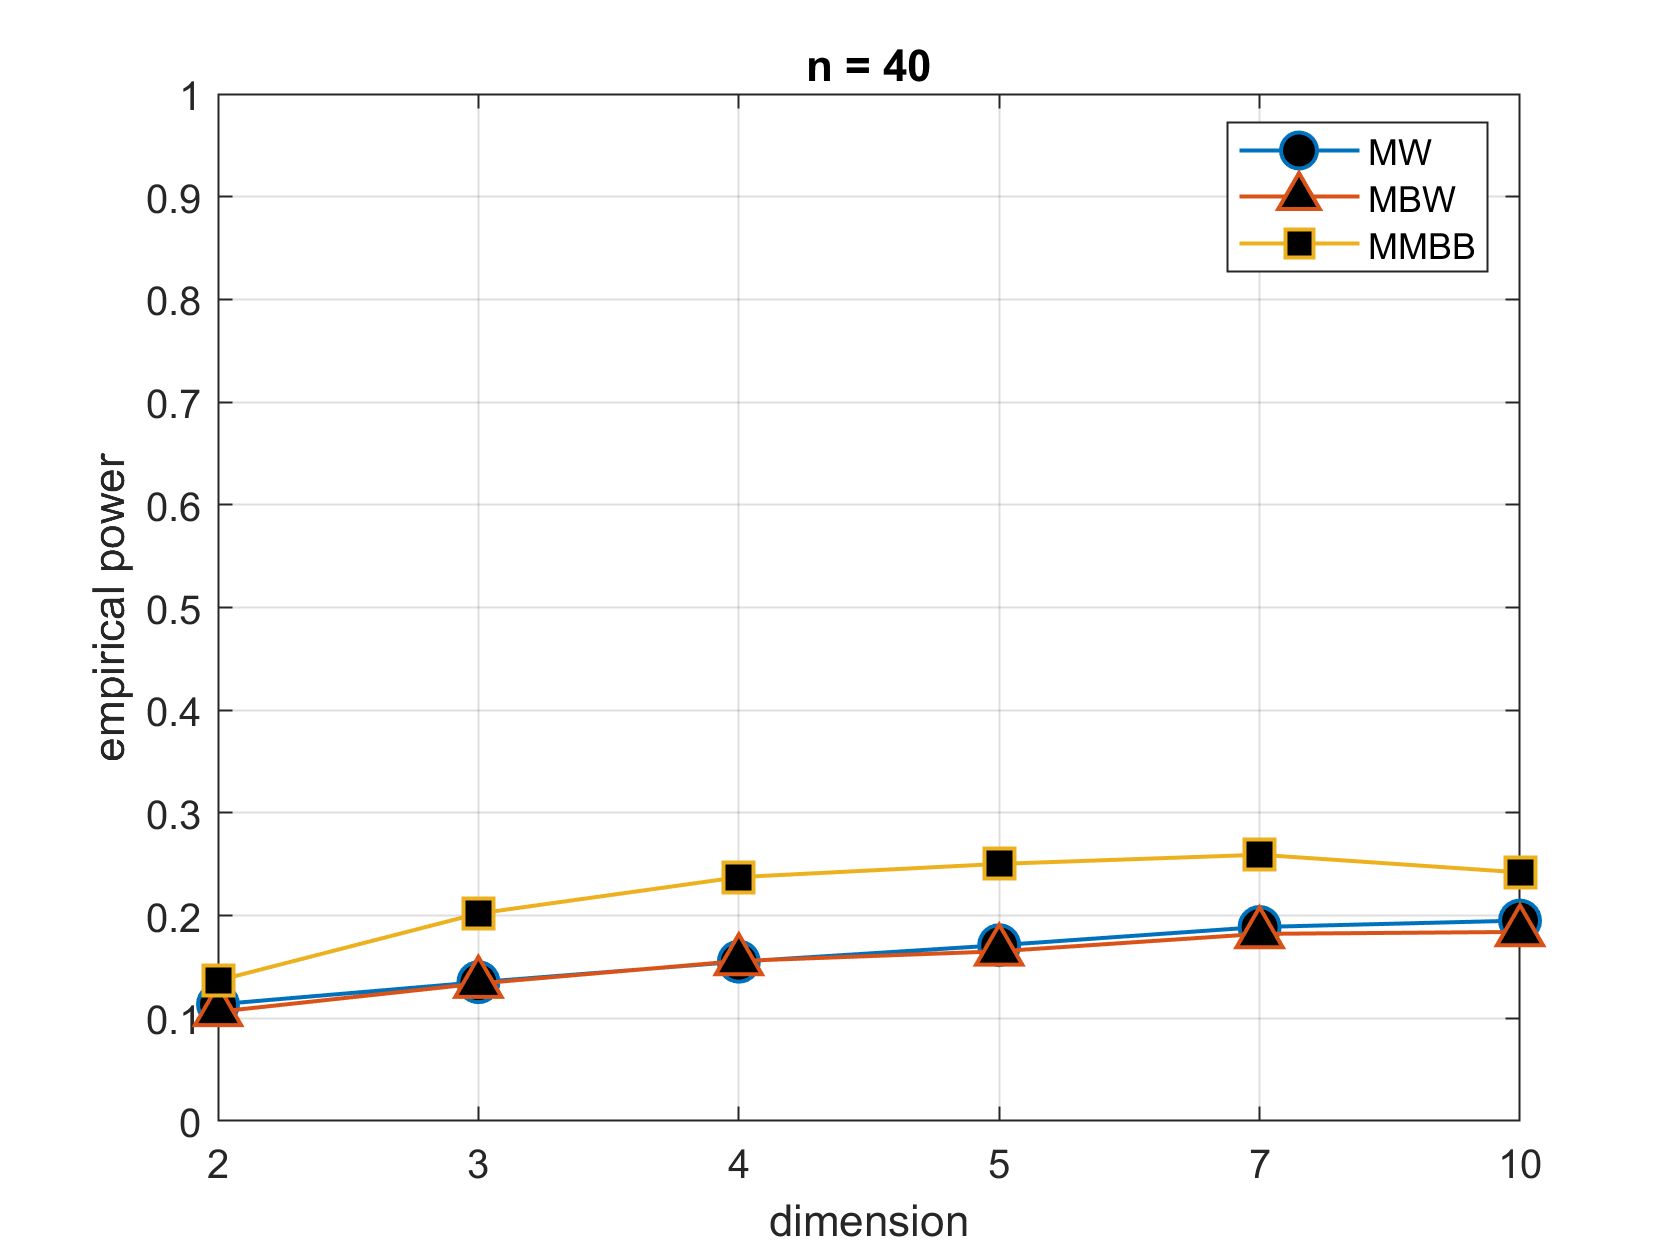

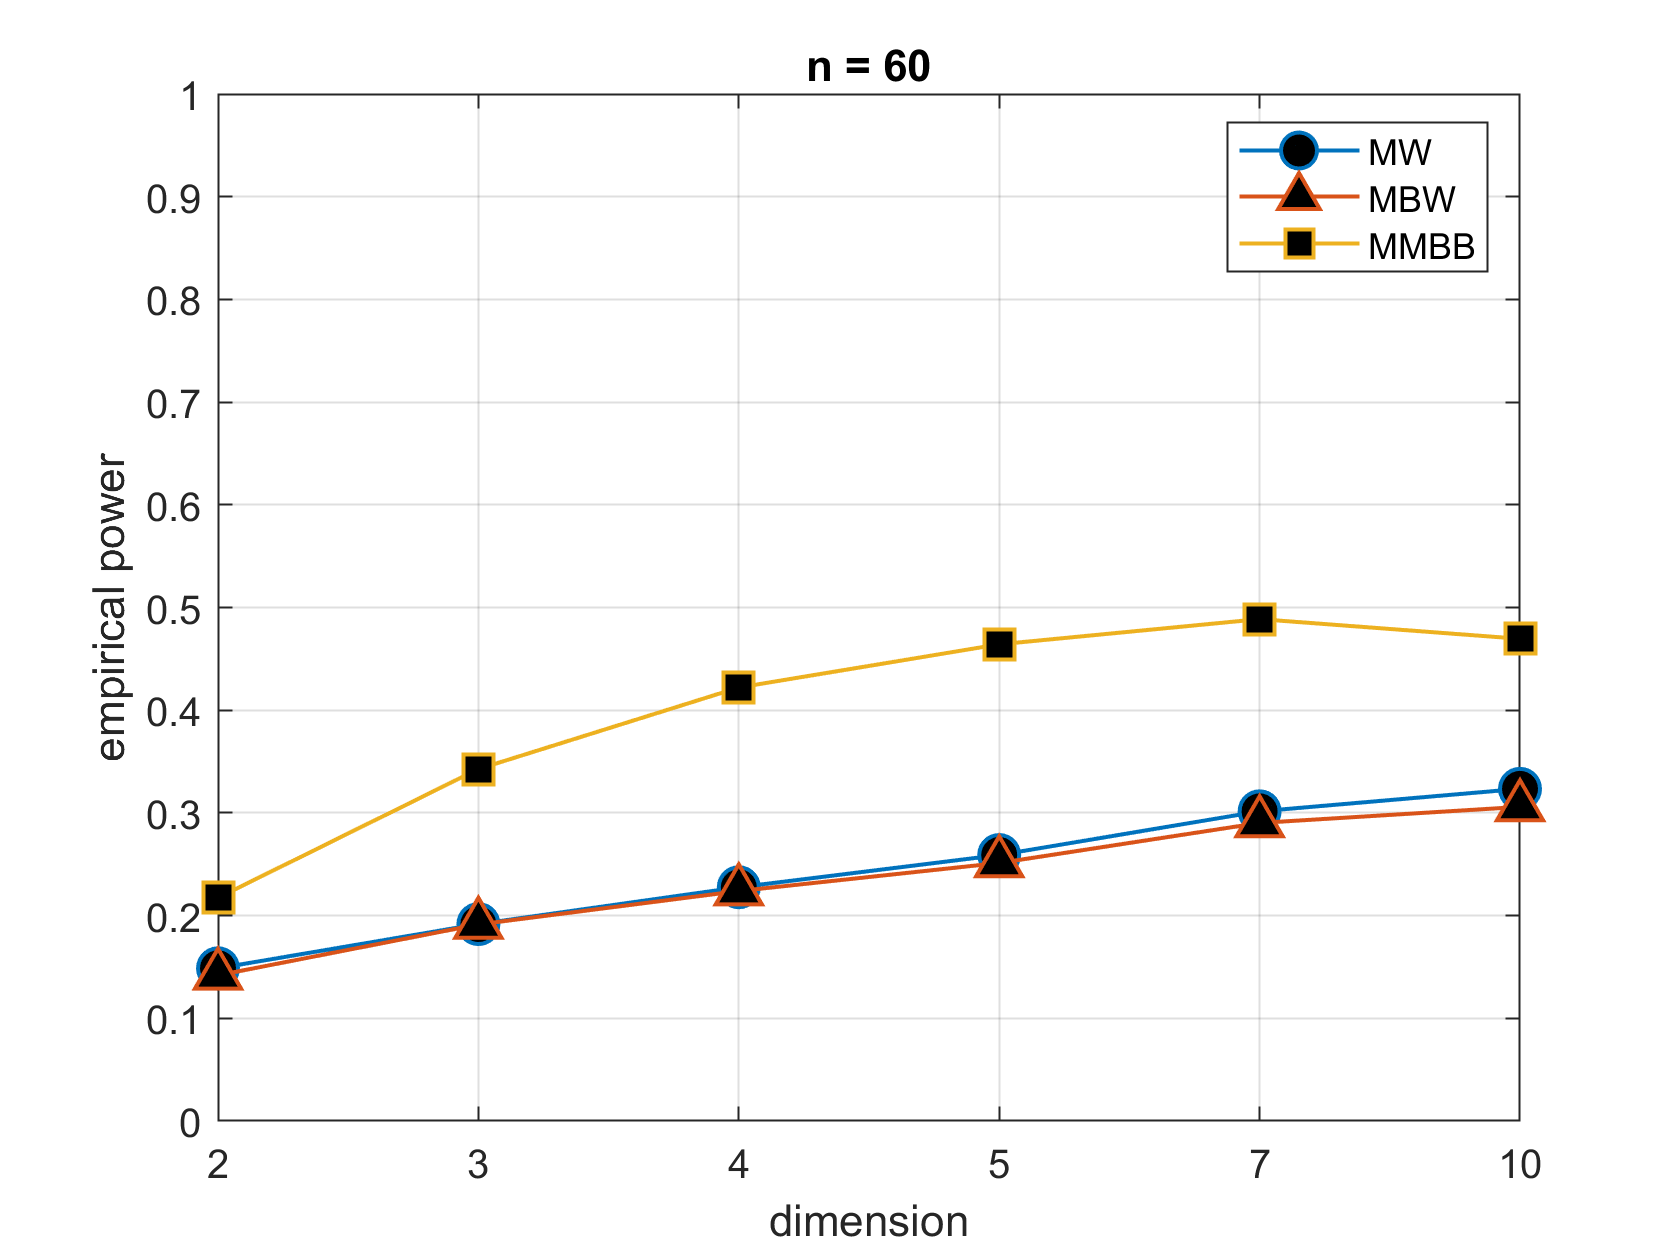

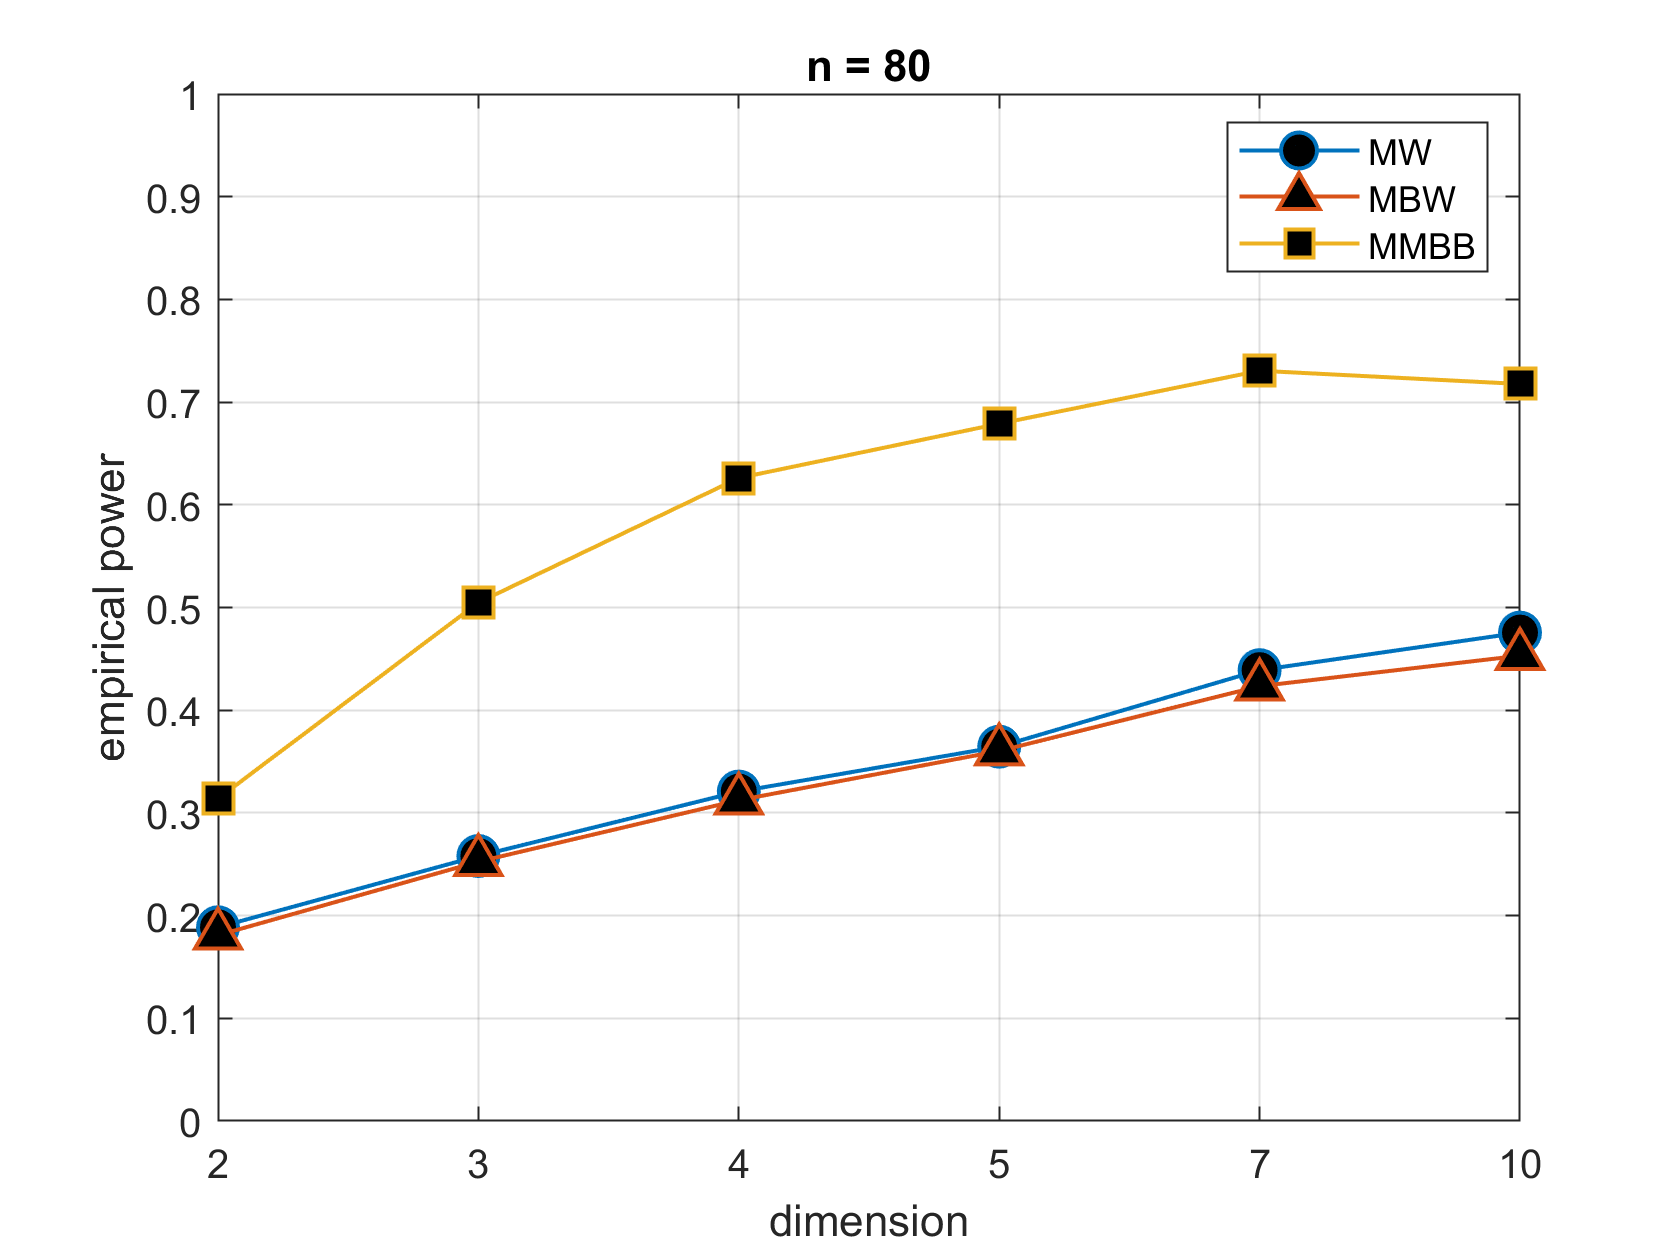

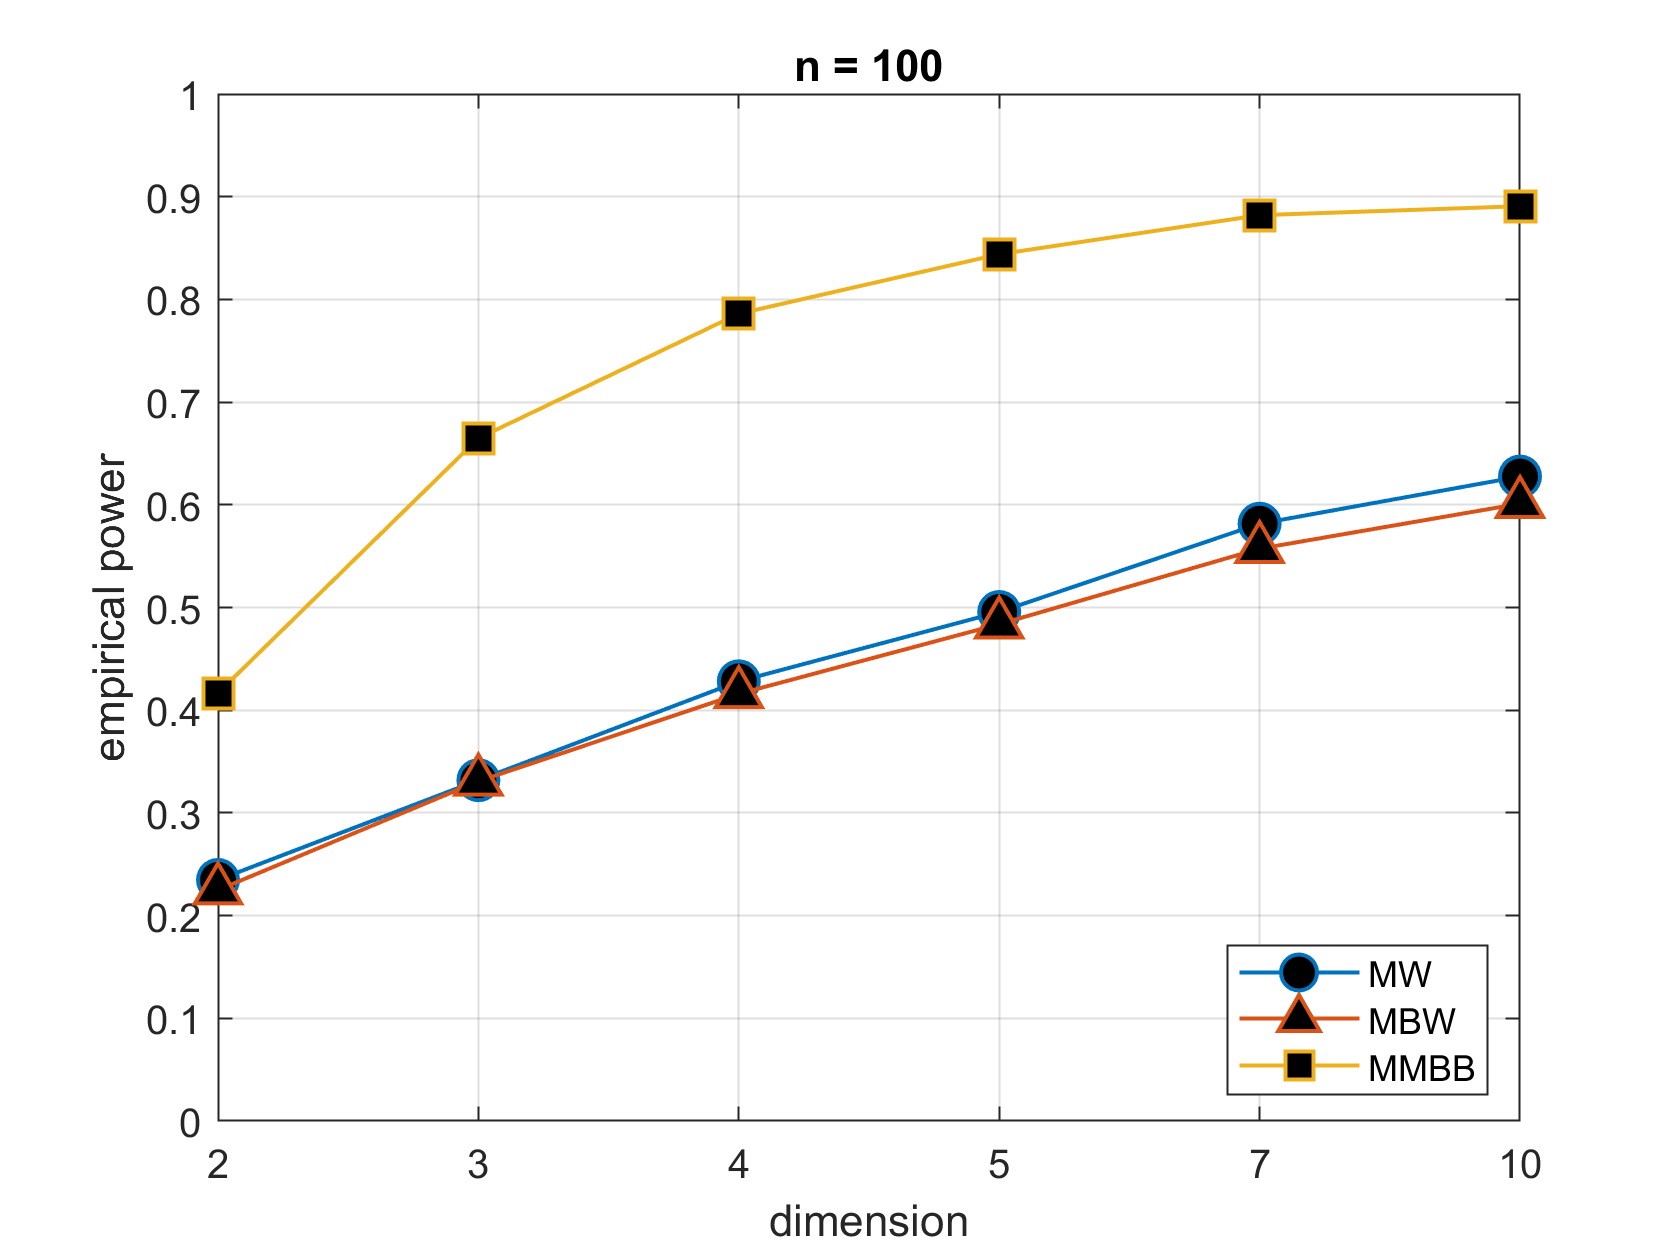

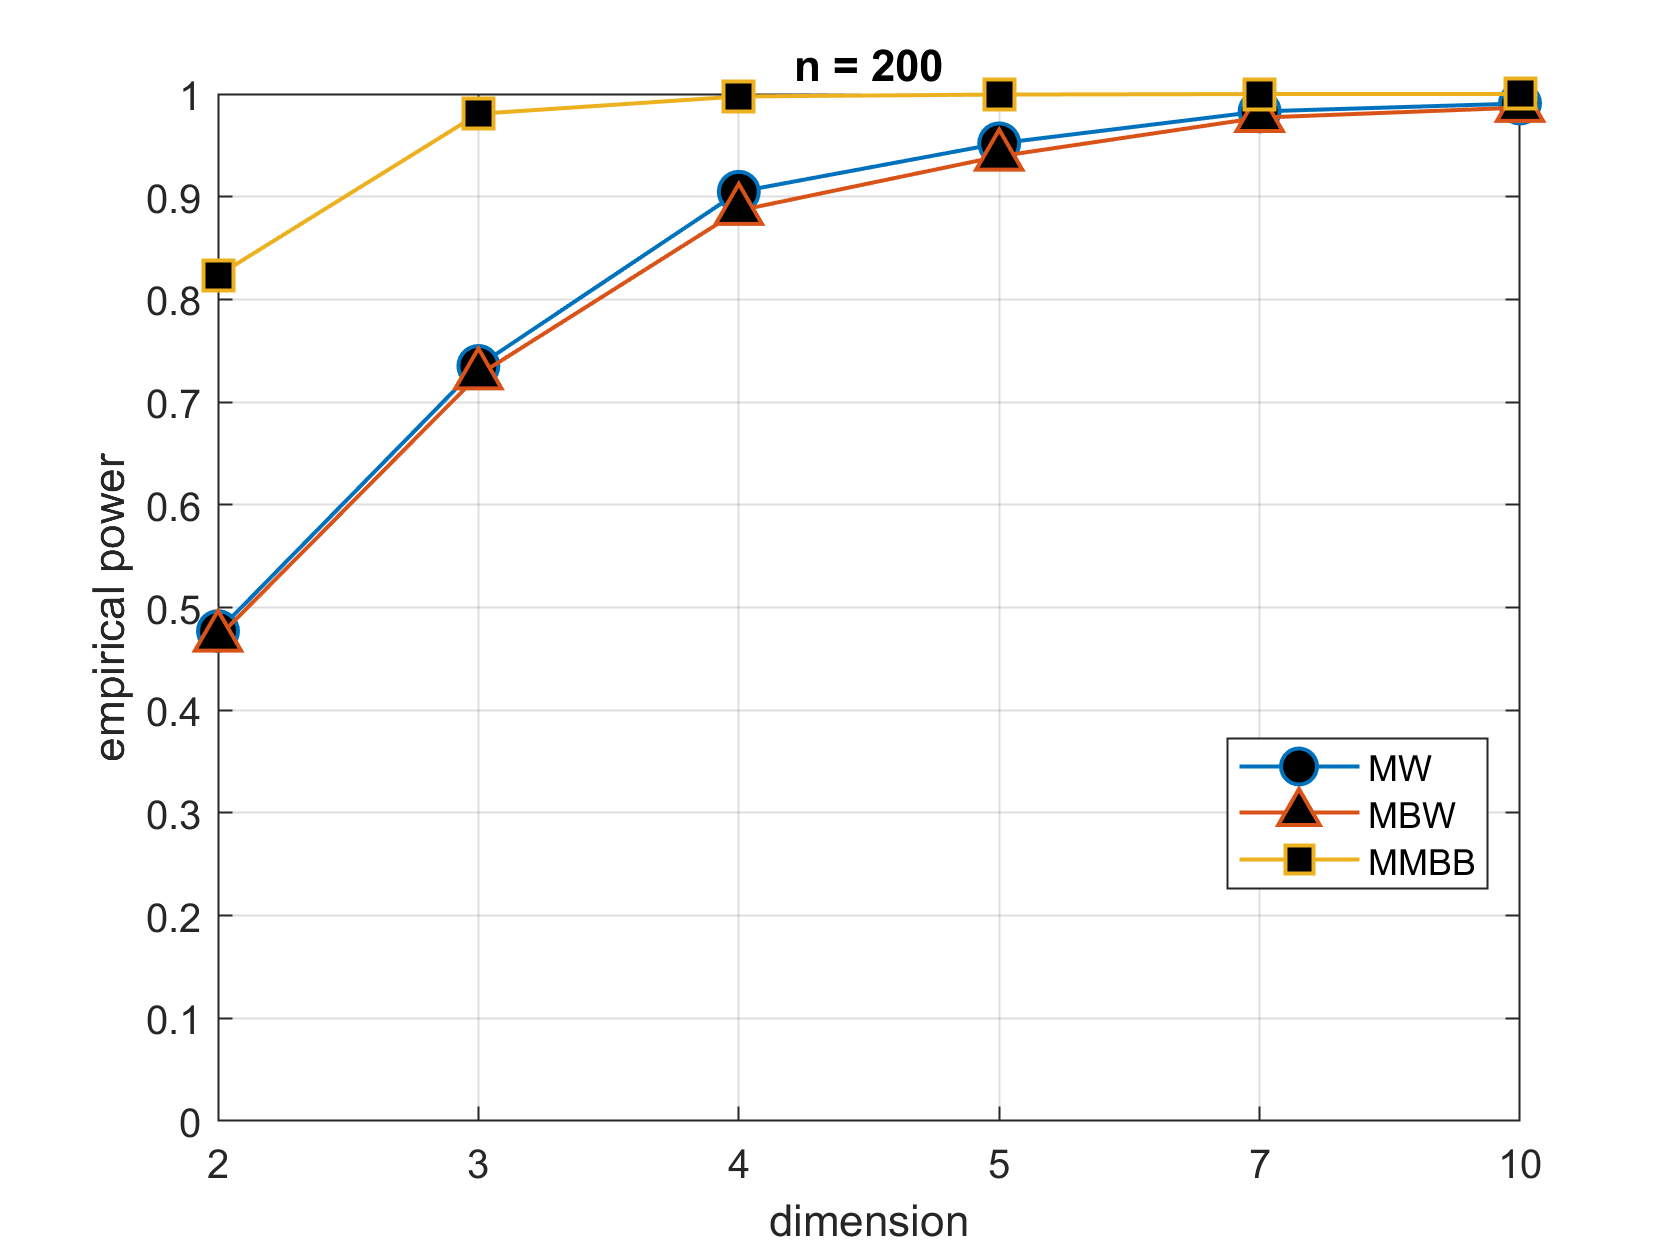

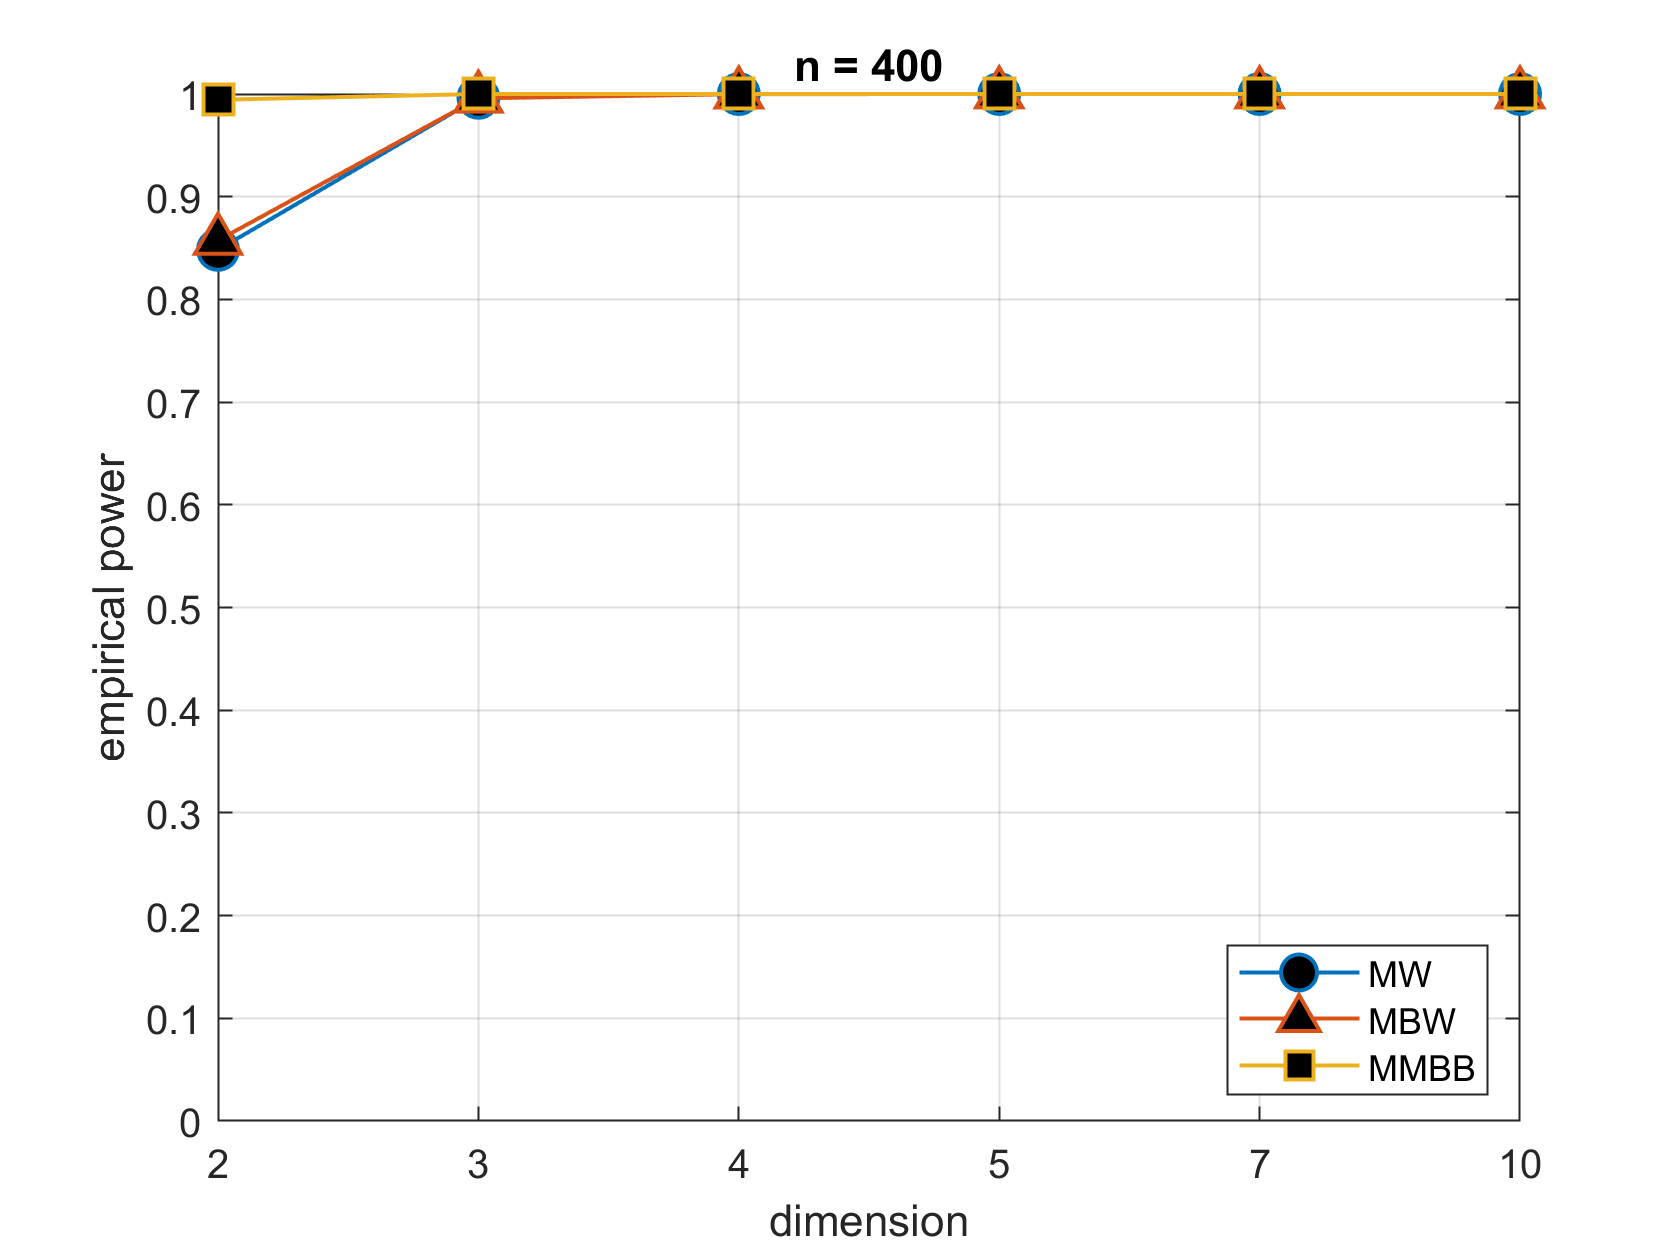

load(dirpath+filename(fIdx))
n = [20:20:100 200 400];
d = [2 3 4 5 7 10];
w = 1;
for ni=1:length(n)
% ni = 5;
    figure
    plot(POWER_MW(ni,:),'-o', 'LineWidth',w, 'MarkerSize',10,'MarkerFaceColor',[0 0 0],'DisplayName', 'MW')
    hold on
    plot(POWER_MBW(ni,:),'-^', 'LineWidth',w, 'MarkerSize',10,'MarkerFaceColor',[0 0 0],'DisplayName', 'MBW')
    plot(POWER_MMBB(ni,:),'-s', 'LineWidth',w, 'MarkerSize',10, 'MarkerFaceColor',[0 0 0], 'DisplayName', 'MMBB')
%     plot(POWER_ALL(ni,:,1),'-.*', 'DisplayName', 'MK') % MK
%     plot(POWER_ALL(ni,:,2),'-.+','LineWidth',w, 'DisplayName', 'MS') % MS
%     plot(POWER_ALL(ni,:,3),'-.|','LineWidth',w, 'DisplayName', 'HZ') % H141
%     plot(POWER_ALL(ni,:,4),'-.>','LineWidth',w, 'DisplayName', 'B(H_S)') % HS
%     plot(POWER_ALL(ni,:,5),'--<','LineWidth',w, 'DisplayName', 'B(H_L)') % HL
%     plot(POWER_ALL(ni,:,7),'--d','LineWidth',w, 'DisplayName', 'WH') % WANG
    hold off
    title("n = " + num2str(n(ni)))
    xticklabels(d)
    ylabel('empirical power')
    xlabel('dimension')
    grid on
    legend('Location','best')
    if fIdx == 16 
        ylim([0.00 0.02])
    elseif fIdx == 17
        ylim([0.04 0.06])
    else
        ylim([0 1])
    end
end